# Tarea Ecuaciones diferenciales

Cecilia Vásquez 150482

Maritrini García 151490


$$y^{\prime } =t$$


y0=1;
f= @(t,y) t;
[t,y] = ivps(f,0,y0,0.1,2,'midpoint')

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y =     1.0000    1.0050    1.0200    1.0450    1.0800    1.1250    1.1800    1.2450    1.3200    1.4050    1.5000    1.6050    1.7200    1.8450    1.9800    2.1250    2.2800    2.4450    2.6200    2.8050    3.0000


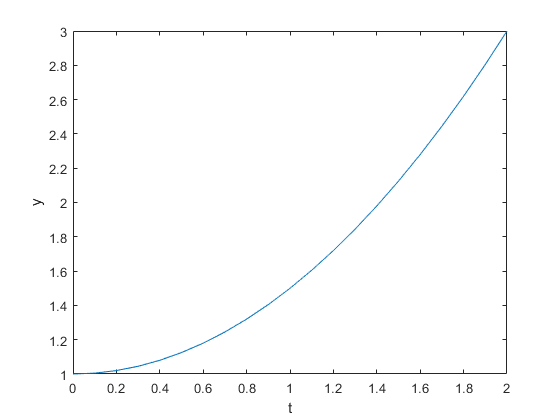

plot(t,y)
xlabel('t');
ylabel('y');

$y^{\prime } =t^2$y

y0=1;
f= @(t,y) t^2*y;
[t,y] = ivps(f,0,y0,0.1,2,'trapezoide')

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y =     1.0000    1.0005    1.0030    1.0095    1.0222    1.0434    1.0757    1.1224    1.1875    1.2767    1.3974    1.5603    1.7806    2.0809    2.4952    3.0754    3.9036    5.1118    6.9179    9.6918   14.0793


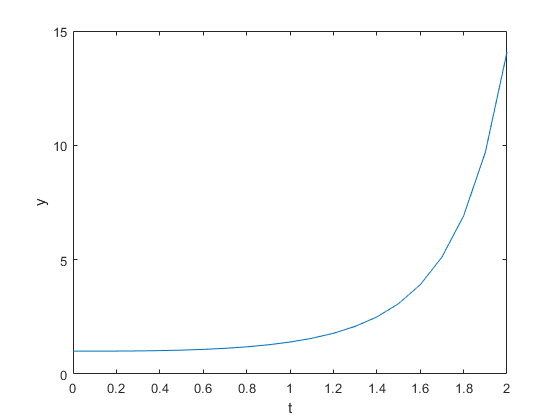

plot(t,y)
xlabel('t');
ylabel('y');


$$y^{\prime } =2\left(t+1\right)y$$


y0=1;
f= @(t,y) 2*(t+1)*y;
[t,y] = ivps(f,0,y0,0.1,2,'euler')

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y =     1.0000    1.2000    1.4640    1.8154    2.2874    2.9278    3.8062    5.0241    6.7323    9.1560   12.6352   17.6893   25.1188   36.1711   52.8099   78.1586  117.2379  178.2016  274.4305  428.1116  676.4163


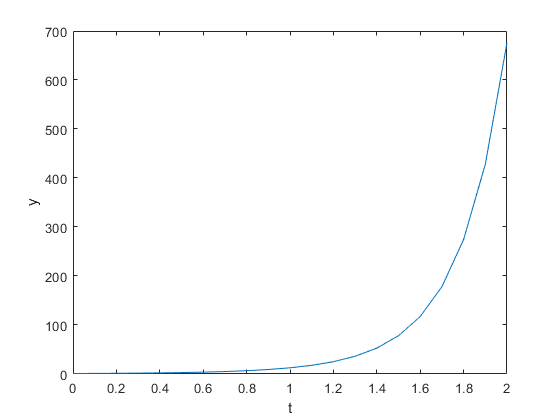

plot(t,y)
xlabel('t');
ylabel('y');

$y^{\prime } =t^2$y   Solución con rk4

y0=1;
f= @(t,y) t^2*y;
[t,y] = frk4(f,0,2,y0,21)

t =          0    0.0952    0.1905    0.2857    0.3810    0.4762    0.5714    0.6667    0.7619    0.8571    0.9524    1.0476    1.1429    1.2381    1.3333    1.4286    1.5238    1.6190    1.7143    1.8095    1.9048    2.0000


y =     1.0000
    1.0003
    1.0023
    1.0078
    1.0186
    1.0366
    1.0642
    1.1038
    1.1589
    1.2336


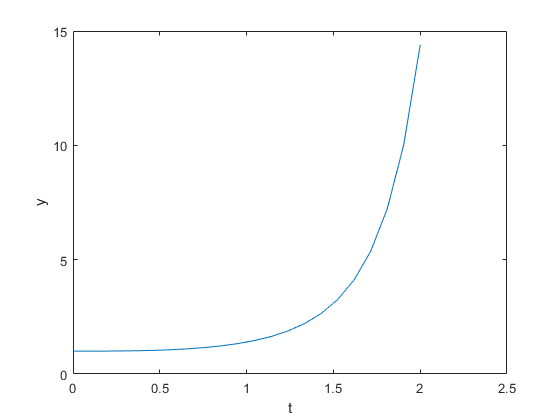

plot(t,y)
xlabel('t');
ylabel('y');

$y^{\prime } =2\left(t+1\right)y$  Solución con rk4

y0=1;
f= @(t,y) 2*(t+1)*y;
[t,y] = ivps(f,0,y0,0.1,2,'euler')

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y =     1.0000    1.2000    1.4640    1.8154    2.2874    2.9278    3.8062    5.0241    6.7323    9.1560   12.6352   17.6893   25.1188   36.1711   52.8099   78.1586  117.2379  178.2016  274.4305  428.1116  676.4163


plot(t,y)
xlabel('t');
ylabel('y');

function [t,y] = frk4(f,a,b,y0,n)
% Runge-Kutta method
% [a, b] intervalo de la función 
%y0 condición inicial 
% n = número de subintervalos 
%f = función dependiente de y ,t
h = (b-a)/n;
halfh = h/2;
y(1,:)= y0;
t(1)= a;
h6 = h/6;
for i = 1 : n
    t(i+1) = t(i) + h;
    th2 = t(i) + halfh;
    s1 = f(t(i), y(i,:));
    s2 = f(th2, y(i,:) + halfh * s1);
    s3 = f(th2, y(i,:) + halfh * s2);
    s4 = f(t(i+1), y(i,:) + h * s3);
    y(i+1,:) = y(i,:) + (s1 + s2+s2 + s3+s3 + s4) * h6;
end
end 